addpath('your file path');

filename = "penguins.csv";
penguins = readtable(filename);

summary(penguins);


penguins: 344×7 table

Variables:

    species: categorical (3 categories)
    island: categorical (3 categories)
    bill_length_mm: double
    bill_depth_mm: double
    flipper_length_mm: double


penguins.species = categorical(penguins.species);
penguins.island = categorical(penguins.island);
penguins.sex = categorical(penguins.sex);

penguins1 = rmmissing(penguins);

penguins1.bill_length_mm

ans =    39.1000
   39.5000
   40.3000
   36.7000
   39.3000
   38.9000
   39.2000
   41.1000
   38.6000
   34.6000


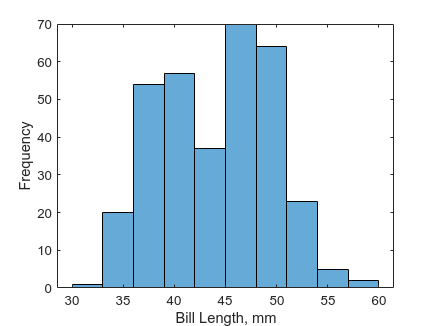

% The whole sample histogram

histogram(penguins1.bill_length_mm,"DisplayName","bill_length_mm","DisplayStyle","bar");
xlabel("Bill Length, mm")
ylabel("Frequency")

gentoo = penguins1(penguins1.species == "Gentoo",:); 
chinstrap = penguins1(penguins1.species == "Chinstrap",:);
adelie = penguins1(penguins1.species == "Adelie",:);

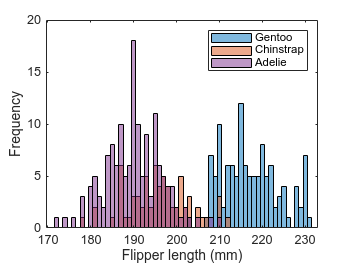

% Different species histogram

h(1) = histogram(gentoo.flipper_length_mm, "FaceAlpha",0.5, SeriesIndex=1);
hold on
h(2) = histogram(chinstrap.flipper_length_mm, "FaceAlpha",0.5, SeriesIndex=2);
h(3) = histogram(adelie.flipper_length_mm, "FaceAlpha",0.5, SeriesIndex=4);
hold off 
xlabel("Flipper length (mm)")
ylabel("Frequency")
legend(h,"Gentoo", "Chinstrap", "Adelie")

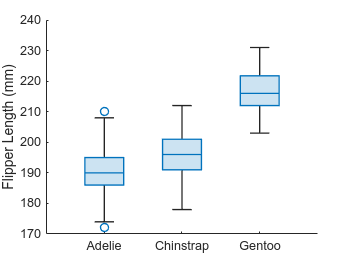

% BOXPLOT

figure()
boxchart(penguins1.species, penguins1.flipper_length_mm)
ylabel("Flipper Length (mm)")

% MIN & MAX on the histogram

histogram(penguins1.flipper_length_mm)
xlabel("Flipper Length (mm)")
ylabel("Frequency")
title("Distribution of penguin flipper lengths")

min_flip = min(penguins1.flipper_length_mm)

min_flip = 172

xline(min_flip, "LineWidth",5)

max_flip = max(penguins1.flipper_length_mm)

max_flip = 231

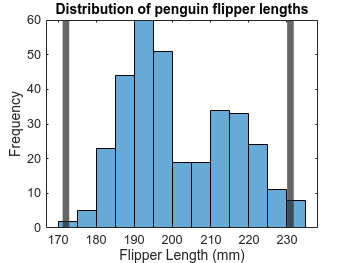

xline(max_flip, "LineWidth",5)

% Mean, Meadian, Mode

histogram(penguins1.flipper_length_mm, "EdgeColor","none") % you can remove the edges by utilzing the "EdgeColor" option
xlabel("Flipper Length (mm)")
ylabel("Frequency")
title("Distribution of penguin flipper lengths")

mean_flip = mean(penguins1.flipper_length_mm)

mean_flip = 200.9670

xline(mean_flip, "--")

median_flip = median(penguins1.flipper_length_mm)

median_flip = 197

xline(median_flip, ":", "LineWidth",1.5)

mode_flip = mode(penguins1.flipper_length_mm)

mode_flip = 190

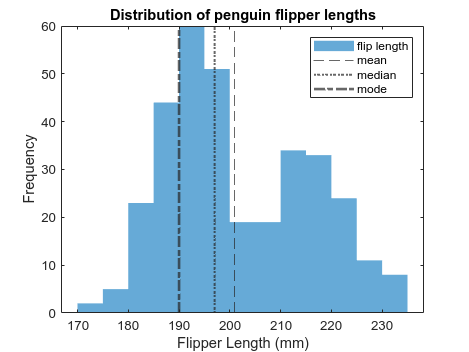

xline(mode_flip, "-.", 'LineWidth',2)
legend ("flip length", "mean", "median", "mode")

% Hypothesis testing

male = penguins1(penguins1.sex == "MALE",:);
female = penguins1(penguins1.sex == "FEMALE",:);

class(penguins1.body_mass_g)

ans = 'double'

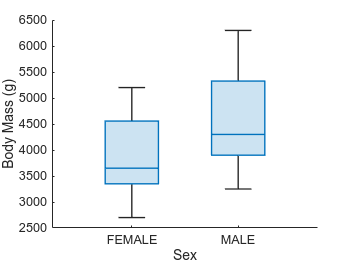

% Look on the hypothesis in boxplot
boxchart(penguins1.sex, penguins1.body_mass_g) % plot body mass, broken up by sex 
xlabel("Sex")
ylabel("Body Mass (g)")

[h, p] = ttest2(male.body_mass_g, female.body_mass_g)

h = 1

p = 4.8972e-16

[h, p] = ttest2(male.bill_length_mm, female.bill_length_mm, "Tail", "right")

h = 1

p = 5.4713e-11

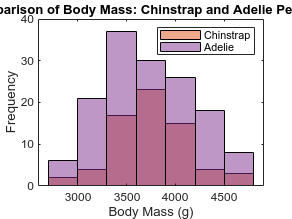

%%%%% --- Q1 --- %%%%%

% Load data
penguins = readtable('penguins.csv');
penguins = rmmissing(penguins);

% Filter Chinstrap penguins
chinstrap = penguins(strcmp(penguins.species, 'Chinstrap'), :);
% Filter Adelie penguins
adelie = penguins(strcmp(penguins.species, 'Adelie'), :);


% Requested Histogram
figure
h(1) = histogram(chinstrap.body_mass_g, 'FaceAlpha', 0.5, SeriesIndex=2);

%%%%% --- Q2 --- %%%%%
hold on
% Requested Histogram for Adelie
h(2) = histogram(adelie.body_mass_g, 'FaceAlpha', 0.5, SeriesIndex=4);

%%%%% --- Q3 --- %%%%%
hold off

%%%%% --- Q4 --- %%%%%
xlabel('Body Mass (g)')
ylabel('Frequency')
title('Comparison of Body Mass: Chinstrap and Adelie Penguins')

%%%%% --- Q5 --- %%%%%
legend('Chinstrap', 'Adelie')